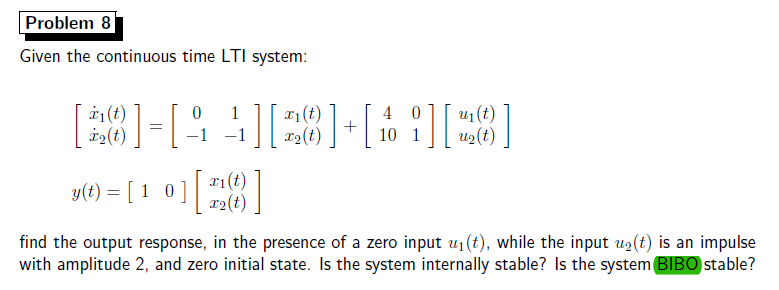

s=tf('s');


A=[0 1;
   -1 -1];
B=[4 0;
   10 1]';
C=[1 0];
D=[0 0];
x0=[0]'

x0 =      0.0000e+000


U=[0 2/s];

sys=ss(A,B,C,D);

H=tf(sys)

H =
 
  From input 1 to output:
    4 s + 4
  -----------
  s^2 + s + 1
 
  From input 2 to output:
   10 s + 11
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.




U=[0 2/s]';
Y=minreal((zpk(C*B*U*inv(s*eye(2)-A))));

% pole(H)
% rlocus(H(1),'b',H(2),'k')


All eigenvalues are negative so the system is stable

## **RESIDUAL METHOD**



Y=(97.95*s^6*+2.25e04*s^5+1.65e06*s^4+3.96e07*s^3+1.73e08*s^2)/(394.2*s^8+1.095e05*s^7+1.75e07*s^6+1.27e09*s^5+2.85e10*s^4+1.3e11*s^3)

Y =
 
             2.204e06 s^11 + 1.65e06 s^4 + 3.96e07 s^3 + 1.73e08 s^2
  -----------------------------------------------------------------------------
  394.2 s^8 + 109500 s^7 + 1.75e07 s^6 + 1.27e09 s^5 + 2.85e10 s^4 + 1.3e11 s^3
 
Continuous-time transfer function.



[Num,Den]=tfdata(Y(1,1),'v')

Num =      2.2039e+006     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     0.0000e+000     1.6500e+006    39.6000e+006   173.0000e+006     0.0000e+000     0.0000e+000


Den =      0.0000e+000     0.0000e+000     0.0000e+000   394.2000e+000   109.5000e+003    17.5000e+006     1.2700e+009    28.5000e+009   130.0000e+009     0.0000e+000     0.0000e+000     0.0000e+000



zpk(minreal(Y,10^-3))
[r,p]=residue(Num,Den)





The system is BIBO because the real part of the poles is negative.

## **SIMBOLIC METHOD**

H
clear
syms t f(t) H s

H=(10*s+11)/((s^2+s+1))
frac(H)
f(t)=piecewise(t<0,0,0<t<0.5,heaviside(0.25),t>0.5,0)
assume(t,'positive')
y=vpa(simplify(ilaplace(laplace(f)*H)),4)

fplot(y,'g-o')
hold on
fplot(2.3094*exp(-0.5*t)*cos(0.866*t-1.5708),'r')
hold off